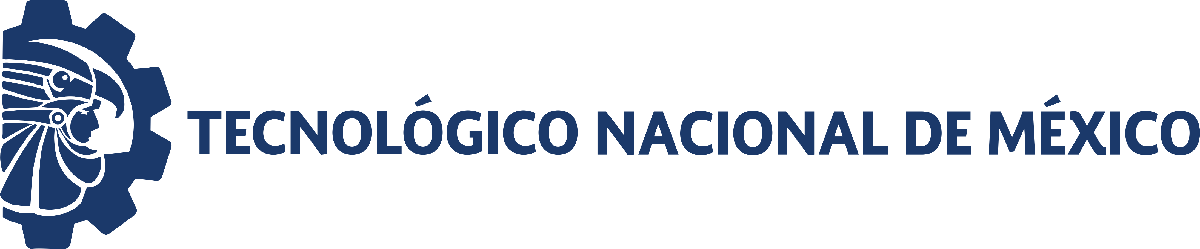                                 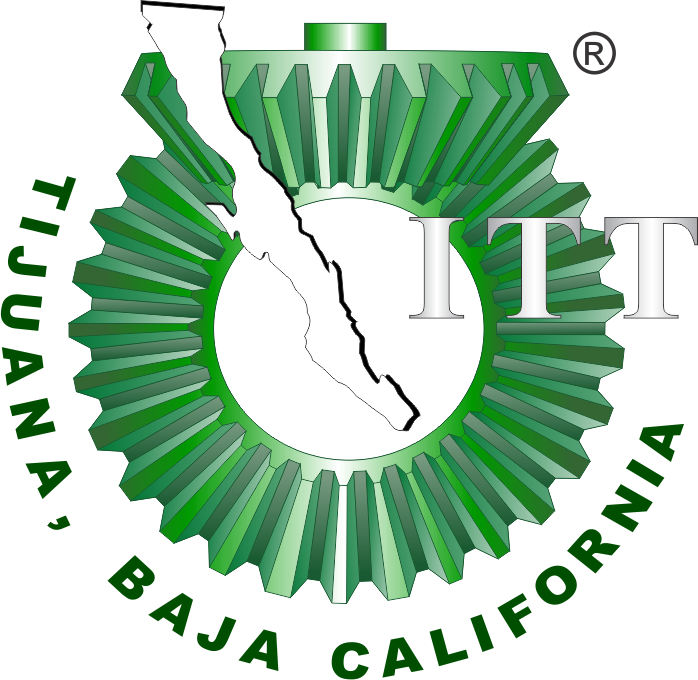

# Proyecto: Sistema Urinario

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

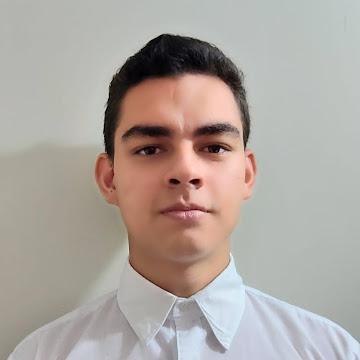            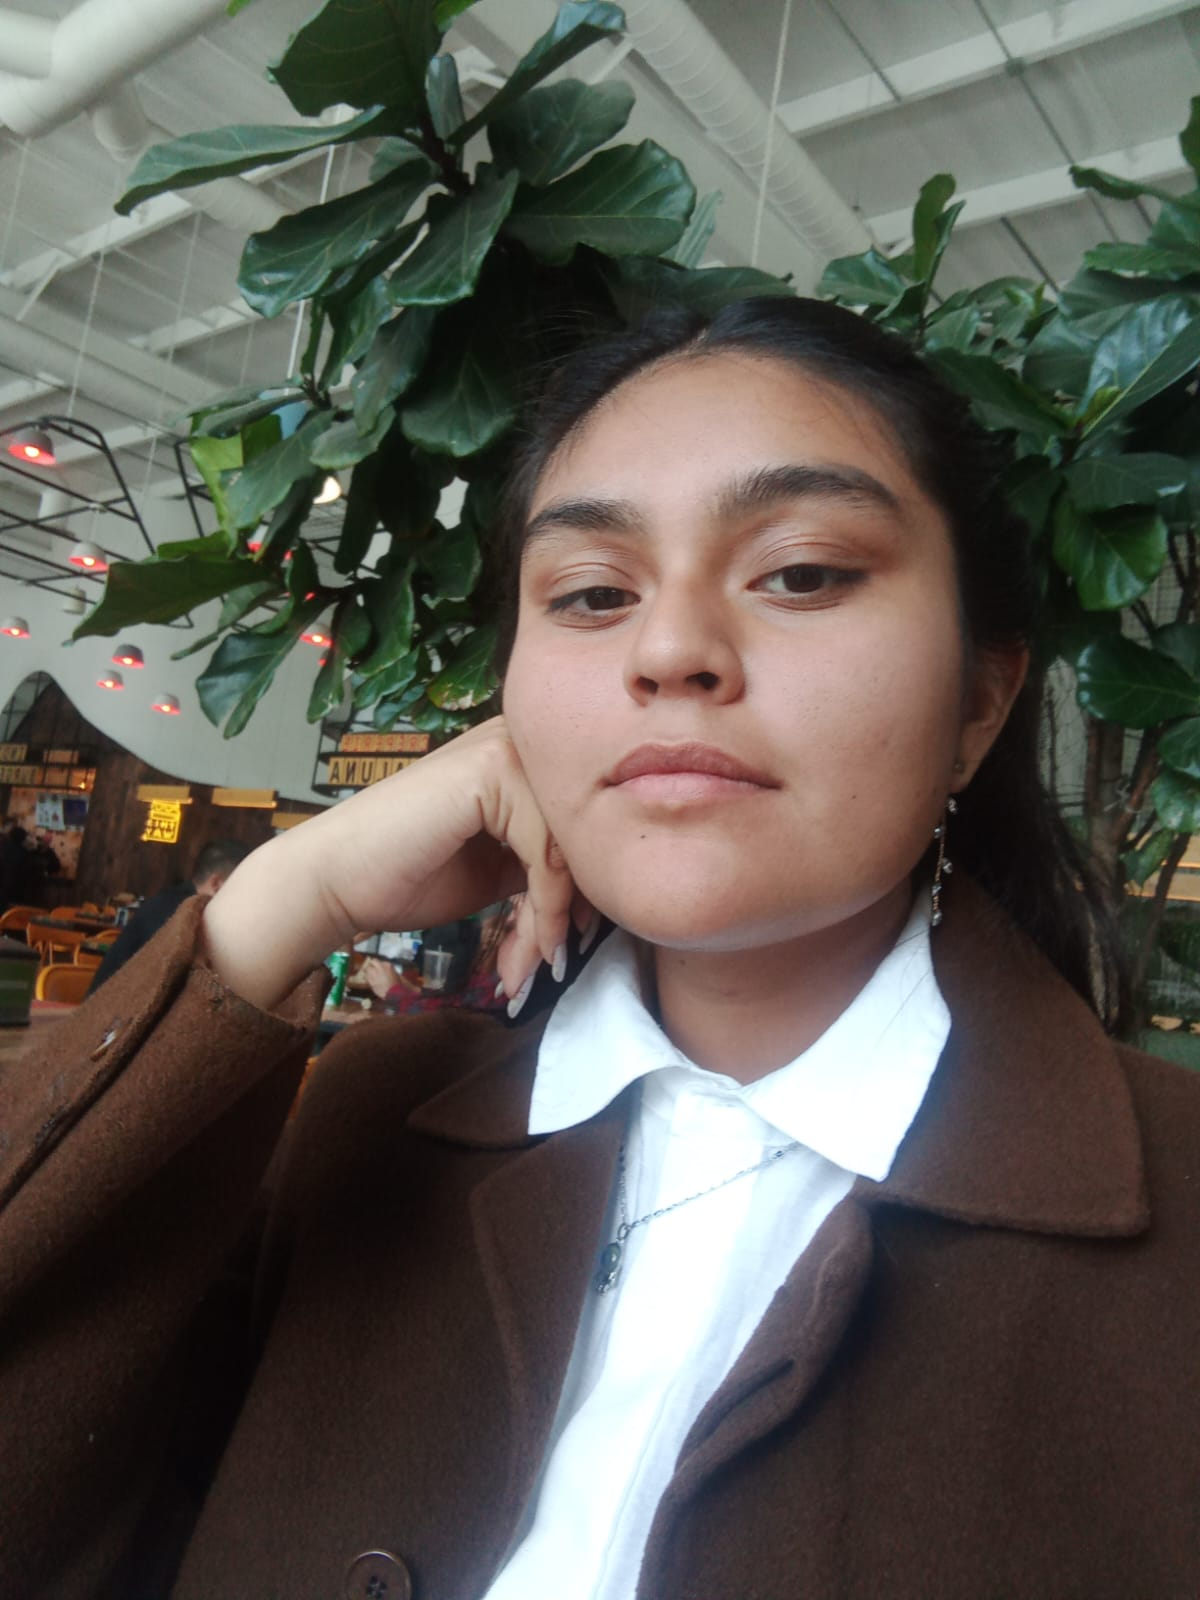            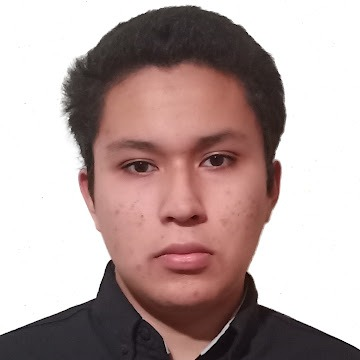            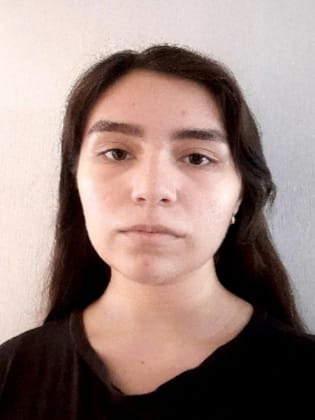

Nombre de los alumnos: **Aron Cervantes Armenta - Bricia Idalia Arellano Salones - Alejandro Ramirez Zepeda - Abigail Villa Camacho**

Números de control: **22211750 -** **22211746 - ** **22211765 -** **22212276**

Correos institucionales: **l22211750@tectijuana.edu.mx - l22211746@tectijuana.edu.mx - l22211765@tectijuana.edu.mx - l22212276@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

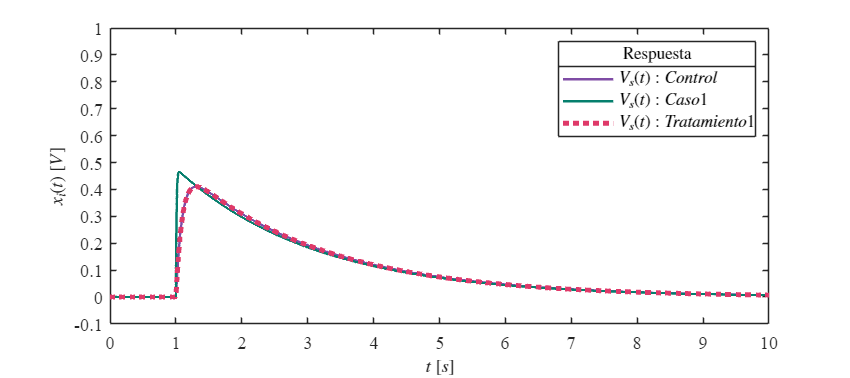

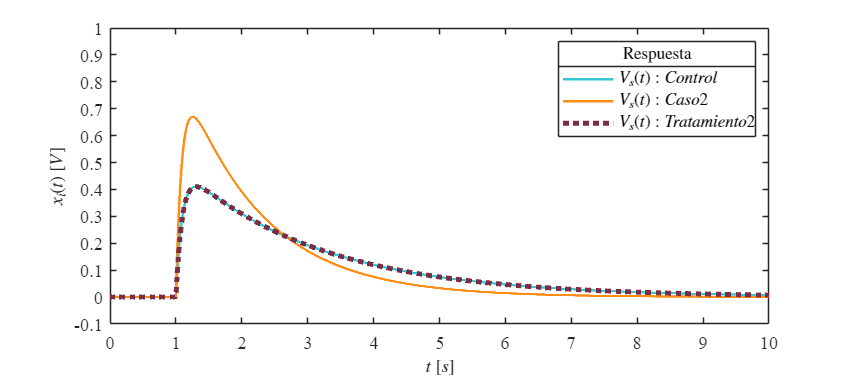

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23tb';
parameters.MaxStep = '1E-3';
Signal = 'Ve(t)';
x = sim(file,parameters);
plotsignals(x.t,x.Vs1,x.Vs2,x.Vs3,x.Vs4,x.Vs5,Signal)

## Funcion: Respuesta a las señales

function plotsignals(t,Vs1,Vs2,Vs3,Vs4,Vs5,Signal)

    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,2,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [127,76,165;
                5,127,109;
                223,57,105]/255;
    colororder(mycolors);

    p = plot(t,Vs1,'-',t,Vs2,'-',t,Vs4,':',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',3);
    L = legend('$V_{s}(t): Control$','$V_{s}(t): Caso 1$','$V_{s}(t): Tratamiento 1$');
    set(L,'Interpreter','Latex','FontSize',10,'Box','On','Location','NorthEast');
    title(L,'Respuesta','FontSize',10);
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11);
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11);
    xlim([0,10]); xticks(0:1:10);
    ylim([-0.1,1]); yticks(-0.1:0.1:1);

    exportgraphics(gcf,[Signal,'_Caso_1.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'_Caso_1.png'],'ContentType','Vector')


    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,2,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [51,199,216;
                255,141,20;
                123,45,67]/255;
    colororder(mycolors);

    p = plot(t,Vs1,'-',t,Vs3,'-',t,Vs5,':',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',3);
    L = legend('$V_{s}(t): Control$','$V_{s}(t): Caso 2$','$V_{s}(t): Tratamiento 2$');
    set(L,'Interpreter','Latex','FontSize',10,'Box','On','Location','NorthEast');
    title(L,'Respuesta','FontSize',10);
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11);
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11);
    xlim([0,10]); xticks(0:1:10);
    ylim([-0.1,1]); yticks(-0.1:0.1:1);

    exportgraphics(gcf,[Signal,'_Caso_2.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'_Caso_2.png'],'ContentType','Vector')

end